# Super-resolution Chromosome Tracing analysis

Version 1 02/05/2026

Guy Nir: niguy@utmb.edu

## Settings

DataPath='/Users/guynir/Library/CloudStorage/Dropbox-NirLab/Guy Nir/UTMB/Nir Lab/Research/Salmonella/Data/Neutral/18hr_neutral_MgM/MATLAB/PathToData.txt'; % Path to list with all locations to analyze
WalkInfo=readtable('/Users/guynir/Library/CloudStorage/Dropbox-NirLab/Guy Nir/UTMB/Nir Lab/Research/Salmonella/Genome/SalmonelaWalk.txt');
folderPath='/Users/guynir/Library/CloudStorage/Dropbox-NirLab/Guy Nir/UTMB/Nir Lab/Research/Salmonella/Data/Neutral/18hr_neutral_MgM/MATLAB'; % Save folder path
fastaPath='/Users/guynir/Library/CloudStorage/Dropbox-NirLab/Guy Nir/Assemblies/Salmonella/Salmonella.fa'; % Path to the FASTA file of the imaged genome build
circDNA=1; % Change to '1' if this is a circular DNA and '0' if not.
disHmapColorLim=[100,400]; % Sets the distance heatmap color limits
volHmapColorLim=[0,.05]; % Sets the fraction of volume overlap heatmap color limits
CovolHmapColorLim=[-.02, .02];
RMSEHmapColorLim=[60,120]; % Sets the RMSE heatmap color limits
SameTargetFlag=1; % Change this to 1 if you have repeated steps
if SameTargetFlag==1
    SameTargets=[0,20]; % This is where you type which time-points are repeating. Each row is one pair of repeating targets. Column 1 is the first imaged, and column 2 is the re-imaged.
end % if SameTargetFlag==1
Gabrielle21=0; % set to 1 to use Gabrielle's 21 colors - 21 is black. Set to '0' to use the typical matlab blue-to-red
CyclicCMap=0; % set to 1 if looking for a cyclic map. Set to 0 if using Gabriele21 or any other sequntial map.
InterThres=0; % Threshold for interpolation. e.g., if InterThres=0.1, then it will interpolates only if up to 10% of the steps are missing for this walk
notEqSz=1; % Change to '0' if the last step has the same size as the rest of the steps
szGB=56086^2/23.4; ram=64; % Computer RAM
maxArray=szGB*ram;

## Read Data

Path_Table=readtable(DataPath,'Delimiter','comma',ReadVariableNames=false);
Path_Table.Properties.VariableNames="Path";
T_Walks=cell(size(Path_Table,1),1);
numWalks=0;
for i=1:size(Path_Table,1)
    Path=cell2mat(table2array(Path_Table(i,1)));
    T_Walks{i,1}=readtable(Path,'VariableNamingRule','preserve');
    [~,~,ic]=unique(T_Walks{i,1}(:,"Walk-IDs"));
    T_Walks{i,1}(:,"Walk-IDs")=array2table(ic);
    nCols=size(T_Walks{i,1},2);
    T_Walks{i,1}(:,"Walk-IDs")=array2table(table2array(T_Walks{i,1}(:,"Walk-IDs"))+numWalks);
    numWalks=max(table2array(T_Walks{i,1}(:,"Walk-IDs")));
    T_Walks{i,1}(:,nCols+1)=array2table(i);
    T_Walks{i,1}.Properties.VariableNames(nCols+1)="Set-ID";
end % for i=1:size(Path_Table,1)
temp=vertcat(T_Walks{:});
numWalks=numel(unique(table2array(temp(:,"Walk-IDs"))));
ColNames={'Chromosome','Start','End','Number of Oligos','TargetName','time-point'};
WalkInfo.Properties.VariableNames=ColNames;
[chrNames, chrIdx, ~]=unique(WalkInfo(:,'Chromosome'));
chrNames=table2array(chrNames);
ChrSize=zeros(size(chrNames,1),1);
Genome=fastaread(fastaPath);
numChr=numel(unique(WalkInfo(:,'Chromosome')));
for i=1:numChr
    for j=1:size(Genome,1)
        if strcmp(Genome(j).Header,chrNames{i})
            ChrSize(i)=numel(Genome(i).Sequence);
            break
        end % if strcmp(Genome(i).Header,chrNames{i})
    end % for j=1:size(Genome,1)
end % for i=1:numChr
T_Walks=temp;
clear temp;
if notEqSz==1
    LastDomain=(ChrSize(1)-table2array(WalkInfo(end-1,"End")))./1e3; % Put the size in [kb] of the last step if it is different than the rest
end % if notEqSz==1
writetable(T_Walks,fullfile(folderPath,'Data'));
WalksCol=find(strcmp(T_Walks.Properties.VariableNames,"Walk-IDs"));
SetCol=find(strcmp(T_Walks.Properties.VariableNames,"Set-ID"));
Walks=cell(numWalks,1);
for i=1:numWalks
    Walks{i}=table2array(T_Walks(table2array(T_Walks(:,"Walk-IDs"))==i,:));
end % for i=1:numWalks
TPCol=find(strcmp(T_Walks.Properties.VariableNames,"time-point"));
NumTPs=max(table2array(T_Walks(:,"time-point")))+1;
XCol=find(strcmp(T_Walks.Properties.VariableNames,"x"));
YCol=find(strcmp(T_Walks.Properties.VariableNames,"y"));
ZCol=find(strcmp(T_Walks.Properties.VariableNames,"z"));
imIDCol=find(strcmp(T_Walks.Properties.VariableNames,"image-ID"));
psfzCol=find(strcmp(T_Walks.Properties.VariableNames,"psfz"));
preczCol=find(strcmp(T_Walks.Properties.VariableNames,"precisionz"));
precyCol=find(strcmp(T_Walks.Properties.VariableNames,"precisiony"));
precxCol=find(strcmp(T_Walks.Properties.VariableNames,"precisionx"));
maxResCol=find(strcmp(T_Walks.Properties.VariableNames,"maxResidualSlope"));
CycleCol=find(strcmp(T_Walks.Properties.VariableNames,"cycle"));
Z_StepCol = find(strcmp(T_Walks.Properties.VariableNames,"z-step"));
TPs=table2array(unique(T_Walks(:,TPCol)));

## Append data

if exist('T_Clean','var')
    clustCol=find(strcmp(T_Clean.Properties.VariableNames,"cluster-ID"));
    headCols=T_Clean.Properties.VariableNames;
else
    clustCol=find(strcmp(T_Walks.Properties.VariableNames,"cluster-ID"));
    headCols=T_Walks.Properties.VariableNames;
end % if exist('T_Clean','var')
prompt = {'Would you like to append data (n/y)?'};
dlgtitle = 'Adding Walks';
fieldsize = [1 50];
definput = {'n'};
answer = inputdlg(prompt,dlgtitle,fieldsize,definput);
switch answer{1}
    case 'y'
        [file,location] = uigetfile('*.txt','Select the text file with the paths to the csv files to append');
        T_PathAppend=readtable(fullfile(location,file),'Delimiter','comma',ReadVariableNames=false);
        T_PathAppend.Properties.VariableNames="Path";
        T_AppWalks=cell(size(T_PathAppend,1),1);
        numAppWalks=0;
        LastW=Walks{end}(end,WalksCol);
        LastSet=Walks{end}(end,SetCol);
        for i=1:size(T_PathAppend,1)
            Path=cell2mat(table2array(T_PathAppend(i,1)));
            T_AppWalks{i,1}=readtable(Path,'VariableNamingRule','preserve');
            [~,~,ic]=unique(T_AppWalks{i,1}(:,"Walk-IDs"));
            T_AppWalks{i,1}(:,"Walk-IDs")=array2table(ic);
            nCols=size(T_AppWalks{i,1},2);
            T_AppWalks{i,1}(:,"Walk-IDs")=array2table(table2array(T_AppWalks{i,1}(:,"Walk-IDs"))+numAppWalks);
            numAppWalks=max(table2array(T_AppWalks{i,1}(:,"Walk-IDs")));
            T_AppWalks{i,1}(:,nCols+1)=array2table(i);
            T_AppWalks{i,1}.Properties.VariableNames(nCols+1)="Set-ID";
            if isempty(setdiff('amp2',T_AppWalks{i,1}.Properties.VariableNames))
                T_AppWalks{i,1} = removevars(T_AppWalks{i,1},{'amp2'});
            end
            if isempty(setdiff('detection-value',T_AppWalks{i,1}.Properties.VariableNames))
                T_AppWalks{i,1} = removevars(T_AppWalks{i,1},{'detection-value'});
            end
        end % for i=1:size(T_PathAppend,1)
        temp=vertcat(T_AppWalks{:});
        numAppWalks=numel(unique(table2array(temp(:,"Walk-IDs"))));
        T_AppWalks=temp;
        clear temp;
        WalksApp=cell(numAppWalks,1);
        cmapTP=colormap(jet(NumTPs));
        if size(Walks{1},2)>size(T_AppWalks,2)
            szT=[size(T_AppWalks,1),size(Walks{1},2)];
            vT=strings(1,size(Walks{1},2));
            vT(:)="double";
            temp=table('Size',szT,'VariableTypes',vT);
            temp(:,1:clustCol-1)=T_AppWalks(:,1:clustCol-1);
            temp(:,clustCol)=array2table(0);
            temp(:,clustCol+1:end)=T_AppWalks(:,clustCol:end);
            T_AppWalks=temp;
            clear temp
            T_AppWalks.Properties.VariableNames=headCols;
        end % if size(Walks{1},2)>size(T_AppWalks,2)
        for i=1:numAppWalks
            WalksApp{i}=table2array(T_AppWalks(table2array(T_AppWalks(:,"Walk-IDs"))==i,:));
            TPs=unique(WalksApp{i}(:,TPCol));
            NumTP=numel(TPs);
            figure();
            for j=1:NumTPs
                hold on
                idxTP=find(WalksApp{i}(:,TPCol)==j-1);
                %drawnow
                scatter3(WalksApp{i}(idxTP,XCol),WalksApp{i}(idxTP,YCol),WalksApp{i}(idxTP,ZCol),30,cmapTP(j,:),'filled');
            end % for j=1:NumTPs
            title(['Walk ',num2str(i)])
            view(3)
            cmapTP=colormap(jet(NumTPs));
            colorbar
            hold off
            WalksApp{i}(:,WalksCol)=i+LastW;
            WalksApp{i}(:,SetCol)=WalksApp{i}(:,SetCol)+LastSet;
        end %  for i=1:numAppWalks
        if exist('WalkRep','var')
            szRep=numel(WalkRep);
            WalkRep(szRep+1)=size(Walks,1)+1;
        else
            WalkRep=size(Walks,1)+1;
        end % if exist('WalkRep','var')
        Walks=[Walks; WalksApp];
        clear T_AppWalksp WalksApp
        M = cell2mat(Walks);
        T_Walks = array2table(M, 'VariableNames', headCols);
        writetable(T_Walks,fullfile(folderPath,'Data'));
        clear M
    otherwise
end % switch answer
numWalks=size(Walks,1);
NumFixedWalks=numWalks;
ColumnNames=headCols;

## Color maps and repeated targets

If you have imaged the same target more than once set SameTargetFlag to '1'. Then define the same targets in the row below.

if SameTargetFlag==1
    nTPs=NumTPs-1;
else
    nTPs=NumTPs;
end % if SameTargetFlag==1
numColors=256;
WhiteRed=wrcmap(numColors);
WhiteRedUD=flipud(wrcmap(numColors));
gray=[220 220 220]/255; lightGray=[211,211,211]/255;
GenVec=linspace(table2array(WalkInfo(1,"End")),table2array(WalkInfo(end,"End")),size(WalkInfo,1))./1000; % [kb]
% GenVec=((table2array(WalkInfo(:,'End'))-table2array(WalkInfo(:,'Start')))/2+table2array(WalkInfo(:,'Start')))./1e6;
% % [Mb]
if SameTargetFlag==1
    maxStep=SameTargets(end);
    GenVec(size(WalkInfo,1)+1)=0;
else
    maxStep=NumTPs;
end % if SameTargetFlag==1
stepInterval=mean(diff(GenVec(1:nTPs)));

## Distance between Centers

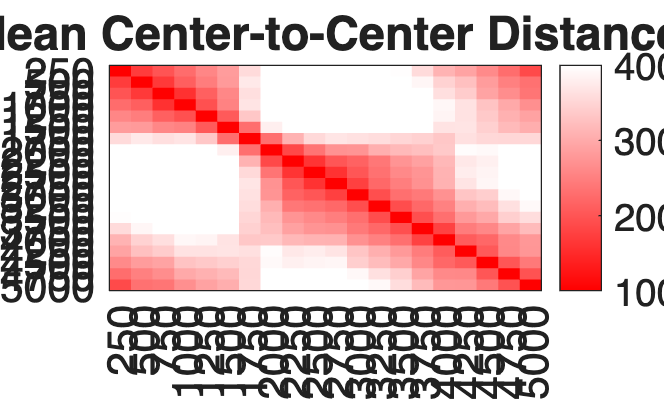

CenterTP=cell(size(Walks,1),1);
CenterTPPrecision=cell(size(Walks,1),1); % Combined x/y/z precision for each weighted centroid
CentD=NaN(NumTPs,NumTPs,size(Walks,1));
sz=[size(CentD,1),size(CentD,2)];
CovDis=CentD; CentNorm=CentD;
centX=CentD; centY=CentD; centZ=CentD;
CompleteWalks_idx=ones(size(CentD,3),1);
for i=1:size(Walks,1)
    Walks{i}=sortrows(Walks{i},TPCol);
    CenterTP{i}=NaN(size(CentD,1),3);
    CenterTPPrecision{i}=NaN(size(CentD,1),3);
    if ~exist('WalkRep','var')
        WalkRep=size(Walks,1)+1;
    end % if ~exists('WalkRep','var')
    for j=1:NumTPs
        idxTP=find(Walks{i}(:,TPCol)==TPs(j));
        if ~isempty(idxTP)
            % Weight each coordinate by inverse variance (1/precision^2).
            % The centroid precision is sqrt(1/sum(weights)).
            coordCols=[XCol,YCol,ZCol];
            precCols=[precxCol,precyCol,preczCol];
            for k=1:3
                coord=Walks{i}(idxTP,coordCols(k));
                prec=Walks{i}(idxTP,precCols(k));
                valid=isfinite(coord) & isfinite(prec) & prec>0;
                if any(valid)
                    weights=1./prec(valid).^2;
                    CenterTP{i}(j,k)=sum(weights.*coord(valid))./sum(weights);
                    CenterTPPrecision{i}(j,k)=sqrt(1./sum(weights));
                end % if any(valid)
            end % for k=1:3
            if any(isnan(CenterTP{i}(j,:)))
                CompleteWalks_idx(i,1)=0;
            end % if any(isnan(CenterTP{i}(j,:)))
        else
            CompleteWalks_idx(i,1)=0;
        end % if ~isempty(idx)
    end % for j=1:MaxTP
    CentD(:,:,i)=squareform_nostats(pdist(CenterTP{i}));
end % for i=1:size(Walks,1)
CompleteWalks_idx=find(CompleteWalks_idx);
CentM_NotNorm=mean(CentD,3,'omitnan');
figure(); heatmap(GenVec(1:nTPs),GenVec(1:nTPs),CentM_NotNorm(1:nTPs,1:nTPs),'Colormap',WhiteRedUD,'ColorMethod','none','ColorLimits',disHmapColorLim,'GridVisible','off','CellLabelColor','none','FontSize',16,'MissingDataColor',lightGray);
title('Mean Center-to-Center Distance')
print(gcf,fullfile(folderPath,'MeanDis.pdf'),'-dpdf','-r300','-bestfit');

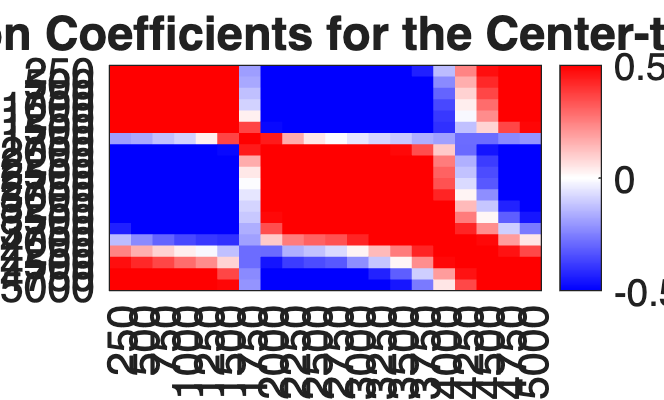

[R,P] = corrcoef(CentM_NotNorm,'Rows','pairwise');
cmapBR = redblue_colormap(256);
figure(); heatmap(GenVec(1:nTPs),GenVec(1:nTPs),R(1:nTPs,1:nTPs),'Colormap',cmapBR,'ColorMethod','none','ColorLimits',[-.5,.5],'GridVisible','off','CellLabelColor','none','FontSize',16,'MissingDataColor',lightGray);
title('Pearson Correlation Coefficients for the Center-to-Center Distance')
print(gcf,fullfile(folderPath,'Pearson C2C.pdf'),'-dpdf','-r300','-bestfit');

## Parabola Fit

minTPs=nTPs; % Minimum number of time-points a trace should have to be included in the analysis
if circDNA==1
    traces=cell(size(Walks,1),size(Walks,2));
    for i=1:size(Walks,1)
        if SameTargetFlag==1
            tpIdx=find(Walks{i,1}(:,TPCol)==SameTargets(2),1,'first');
            traces{i,1}=Walks{i,1}(1:tpIdx-1,:);
        else
            traces{i,1}=Walks{i,1};
        end
    end % for i=1:size(Walks,1)
    exPath=fullfile(folderPath,'ParabolaDiagnostics');
    if ~isfolder(exPath),      mkdir(exPath);      end
    cols.time = TPCol; cols.x = XCol; cols.y = YCol; cols.z = ZCol; cols.traceID = WalksCol;
    opt = struct('numPerm',300,'minTimePoints',minTPs,'minR2',0.2,...
        'plotDiagnostics',true,'showFigures',false,...
        'vertexDevFrac',.1,'vertexTolFrac',6,'alpha',0.7,'exportPath',exPath);
    [keepIdx, statsPara, per] = findParabolicRingTraces(traces, cols, opt);
    traces_kept = traces(keepIdx);
end % if circDNA==1

## Check drift in circular DNA

Set minDrift and maxDrift (line 242; in this example 0, 200) to choose walks where the re-imaging steps (line 243; in this example 1,21) is within a specific range.

if circDNA==1
    minDrift=0; maxDrift=200;
    smallIdx=find(CentD(1,21,:)>=minDrift & CentD(1,21,:)<maxDrift);
    smallIdx=intersect(smallIdx,keepIdx);
    disp([num2str(numel(smallIdx)),' walks within a drift of ',num2str(maxDrift),' nm'])
    midStep=floor(nTPs/2);
    stepDis=NaN(NumFixedWalks,midStep-1);
    stepDiff=zeros(1,midStep-1);
    figure();
    for ii=1:numel(SameTargets)
        for i=1:numel(smallIdx) %NumFixedWalks
            for j=1:midStep-1
                stepDis(i,j)=CentD(SameTargets(ii)+1,midStep+j+1,smallIdx(i))-CentD(SameTargets(ii)+1,midStep-j+1,smallIdx(i));
            end % for j=1:floor(nTPs/2)
        end % for i=1:NumFixedWalks
        for j=1:midStep-1
            stepDiff(j)=(midStep+j)-(midStep-j);
        end % for j=1:floor(nTPs/2)
        stepDMean=median(stepDis,1,'omitnan');
        boxplot(stepDis,stepDiff)
        hold on
        plot(stepDMean,'LineWidth',2)
        xlabel('Step difference')
        ylabel('ED [nm]')
        title([num2str(maxDrift),' nm'])
        legend('1','21','Location','best')
        ylim([-600, 600]);
        yticks(-600:100:600);
        set(gca,'FontSize',14)
        fname=['Step Difference both_',num2str(maxDrift-minDrift),'.pdf'];
        print(gcf,fullfile(folderPath,fname),'-dpdf','-r300','-bestfit');
    end % for ii=1:numel(SameTargets)
    hold off
end % if circDNA==1

## Check drift in circular DNA (contd.)

if SameTargetFlag==1 & circDNA==1
    A=squeeze(CentD(SameTargets(1)+1,SameTargets(2),:));
    A2=squeeze(CentD(SameTargets(1)+1,SameTargets(1)+2,:));
    B=squeeze(CentD(SameTargets(2)+1,SameTargets(2),:));
    B2=squeeze(CentD(SameTargets(2)+1,SameTargets(1)+2,:));
    figure();
    t=tiledlayout(2,2);
    % Tile 1
    ax=nexttile(1);
    histogram(A,round(sqrt(length(A))))
    title('ED 20 --> 1')
    ax.XLim=[0, 1200];
    ax.YLim=[0, 35];
    set(gca,'FontSize',14)
    % Tile 2
    ax=nexttile(2);
    histogram(B,round(sqrt(length(B))))
    ax.XLim=[0, 1200];
    ax.YLim=[0, 35];
    xlabel(t,'ED [nm]')
    ylabel(t,'Frequency')
    title('ED 20 --> 21')
    set(gca,'FontSize',14)
    % Tile 3
    ax=nexttile(3);
    histogram(B2,round(sqrt(length(B2))))
    ax.XLim=[0, 1200];
    ax.YLim=[0, 35];
    title('ED 21 --> 2')
    set(gca,'FontSize',14)
    % Tile 4
    ax=nexttile(4);
    histogram(A2,round(sqrt(length(A2))))
    ax.XLim=[0, 1200];
    ax.YLim=[0, 35];
    title('ED 1 --> 2')
    set(gca,'FontSize',14)
    print(gcf,fullfile(folderPath,'Edge histograms.png'),'-dpng','-r300');
    clear t
    CentM_NotNorm=mean(CentD(:,:,smallIdx),3,'omitnan');
    figure(); heatmap(GenVec(1:nTPs),GenVec(1:nTPs),CentM_NotNorm(1:nTPs,1:nTPs),'Colormap',WhiteRedUD,'ColorMethod','none','ColorLimits',disHmapColorLim,'GridVisible','off','CellLabelColor','none','FontSize',16,'MissingDataColor',lightGray);
    title(['Mean Center-to-Center Distance with 1-21<',num2str(maxDrift),' nm'])
    fname=['MeanDis',num2str(maxDrift),'nm.pdf'];
    print(gcf,fullfile(folderPath,fname),'-dpdf','-r300','-bestfit');
    disSameTargets=mean(CentD(:,SameTargets(1)+1,smallIdx)-CentD(:,SameTargets(2)+1,smallIdx),3,'omitnan');
    x=linspace(0,numel(disSameTargets)-1,numel(disSameTargets));
    plot(x,disSameTargets,'-*','LineWidth',2,'MarkerSize',4,'Color','r')
    xlabel('Contour Distance (s)')
    ylabel('Euclidean Distance [nm]')
    yticks(floor(min(ylim)):50:ceil(max(ylim)))
    title('Mean difference in ED when re-imaging')
    set(gca,'FontName','Arial','FontSize',14)
    print(gcf,fullfile(folderPath,'Dis_SameT.png'),'-dpng','-r300');
    figure(); histogram(CentD(1,21,smallIdx),round(sqrt(numel(smallIdx))));
    ylabel('Frequency')
    xlabel('Center-to-center distance between the re-imaged targets [nm]')
    title('Center-to-Center for 1&21');
    set(gca,'FontName','Arial','FontSize',14)
    print(gcf,fullfile(folderPath,'Histogram_1_21.png'),'-dpng','-r300');
end % if SameTargetFlag==1 & circDNA==1

## Choose core of walks

coreWalks=1;
if coreWalks==1
    if ~exist('oldWalks','var')
        oldWalks=Walks;
        oldCentD=CentD;
    elseif size(oldWalks,1)<size(Walks,1)
        oldWalks=Walks;
        oldCentD=CentD;
    end % if ~exist('oldWalks','var')
    Walks=cell(numel(smallIdx),1);
    tempCenter=cell(numel(smallIdx),1);
    for i=1:numel(smallIdx)
        Walks{i}=oldWalks{smallIdx(i)};
        tempCenter{i}=CenterTP{smallIdx(i)};
    end % for i=1:numel(smallIdx)
    CentD=CentD(:,:,smallIdx);
    CenterTP=tempCenter;
    clear tempCenter
    CentM_NotNorm=mean(CentD(1:nTPs,1:nTPs,:),3,'omitnan');
    centDev=std(CentD(1:nTPs,1:nTPs,:),[],3,'omitnan');
    GenVec=GenVec(1:nTPs);
    fname='MeanDis.pdf';
    figure(); heatmap(GenVec,GenVec,CentM_NotNorm,'Colormap',WhiteRedUD,'ColorMethod','none','ColorLimits',disHmapColorLim,'GridVisible','off','CellLabelColor','none','FontSize',16,'MissingDataColor',lightGray);
    title(['Mean Center-to-Center Distance with 1-21<',num2str(maxDrift)])
    print(gcf,fullfile(folderPath,fname),'-dpdf','-r300','-bestfit');
    temp=vertcat(Walks{:});
    T_Clean=array2table(temp);
    T_Clean.Properties.VariableNames=ColumnNames;% T_Walks.Properties.VariableNames;
    fname=['Data',num2str(maxDrift),'nm_',num2str(numel(smallIdx)),'W'];
    writetable(T_Clean,fullfile(folderPath,fname));
    CompleteWalks_idx=ones(size(CentD,3),1);
    for i=1:size(Walks,1)
        for j=1:NumTPs
            idxTP=find(Walks{i}(:,TPCol)==TPs(j));
            if isempty(idxTP)
                CompleteWalks_idx(i,1)=0;
            end % if isempty(idxTP)
        end % for j=1:NumTPs
    end % for i=1:size(Walks,1)
    clear temp
end % if coreWalks==1

## Save analysis

allvars = whos;
nonfigurevars = {allvars(~strcmp({allvars.class}, 'matlab.ui.Figure')).name};
save(fullfile(folderPath,'AnalyzedData.mat'),"-v7.3",nonfigurevars{:});